# **M1 E3A**

# **TP2 (Image Processing)**

# **Mohammed Akib Iftakher (20215282)**

## Exercise 1 : Generate a noisy image 

### 1. On the image of your choice, generate a Gaussian type noise, uniform then salt and pepper using imnoise. Vary the density of the noise. Keep these images in reserve to evaluate the low pass filters for the next exercise.

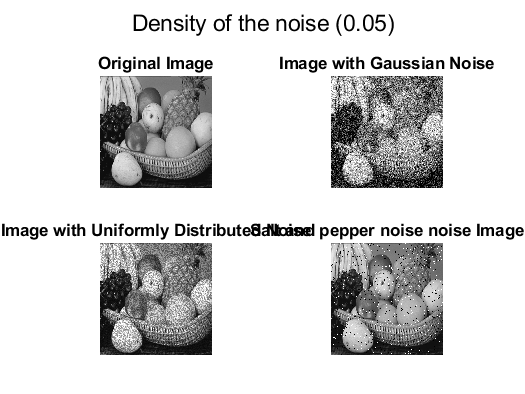

I = imread('FRUIT_LUMI.BMP') ;
fontSize = 10;
figure,
subplot(2, 2, 1);
imshow(I,[]);
axis off;
title('Original Image', 'FontSize', fontSize);
% Add gaussian noise to the image.
noisyGauss = imnoise(I, 'gaussian', 0, 0.05);
% Display the noisy Gaussian  image.
subplot(2, 2, 2);
imshow(noisyGauss,[]);
axis off;
title('Image with Gaussian Noise', 'FontSize', fontSize);

% uniformly distributed random noise with mean 0 and variance 0.05.
var_speckle = 0.05;
noisyUniform = imnoise(I,'speckle',var_speckle);
% Display the noisy Gaussian  image.
subplot(2, 2, 3);
imshow(noisyUniform,[]);
axis off;
title('Image with Uniformly Distributed Noise', 'FontSize', fontSize);

%  salt and pepper noise with noise density 0.05.
d = 0.05;
noisySaltPepper = imnoise(I,'salt & pepper',d) ;
% Display the noisy Gaussian  image.
subplot(2, 2, 4);
imshow(noisySaltPepper,[]);
axis off;
title('Salt and pepper noise noise Image', 'FontSize', fontSize);
sgtitle('Density of the noise (0.05)') 

### Varying the density of the noise (0.1)

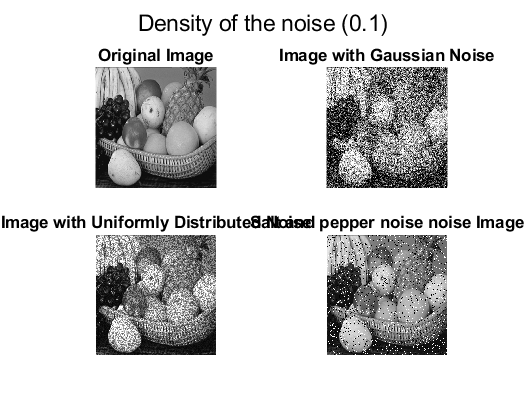

figure,
subplot(2, 2, 1);
imshow(I,[]);
axis off;
title('Original Image', 'FontSize', fontSize);
% Add gaussian noise to the image.
noisyGauss_01 = imnoise(I, 'gaussian', 0, 0.1);
% Display the noisy Gaussian  image.
subplot(2, 2, 2);
imshow(noisyGauss_01,[]);
axis off;
title('Image with Gaussian Noise', 'FontSize', fontSize);

% uniformly distributed random noise with mean 0 and variance 0.1.
var_speckle = 0.1;
noisyUniform_01 = imnoise(I,'speckle',var_speckle);
% Display the noisy Gaussian  image.
subplot(2, 2, 3);
imshow(noisyUniform_01,[]);
axis off;
title('Image with Uniformly Distributed Noise', 'FontSize', fontSize);

%  salt and pepper noise with noise density 0.1.
d = 0.1;
noisySaltPepper_01 = imnoise(I,'salt & pepper',d) ;
% Display the noisy Gaussian  image.
subplot(2, 2, 4);
imshow(noisySaltPepper_01,[]);
axis off;
title('Salt and pepper noise noise Image', 'FontSize', fontSize);
sgtitle('Density of the noise (0.1)') 

Gaussian noise generate via regular sources for example particles thermal vibration as well as separate nature of radiation of warm object. Uniform noise presence is essential in amplitude quantization procedure. It introduces, because of analog data changed over into digital data. Salt-and-Pepper noise is likewise alluded as information drop noise. The picture is not completely ruined by salt & pepper noise rather than some pixel qualities are altered through noise. 

## Exercise 2 : Comparaison of spatial low pass filters Let us define the signal to noise ratio: SNR = 10log10[ $\frac{\sum {I\left(x,y\right)}^2 }{\sum {\left(I_r \left(x,y\right)-I_0 \left(x,y\right)\right)}^2 }$ 2 where $I_r$(x, y) is the filtered image and $I_0$(x, y) the image before degradation with noise. 1. Filter the noisy image with a Gaussian filter of size 3 × 3, 7 × 7 then 11 × 11. Chose the variance in relation with n the size of the filter (n = 6σ + 1). 

**Gaussian filter of size 3 × 3**

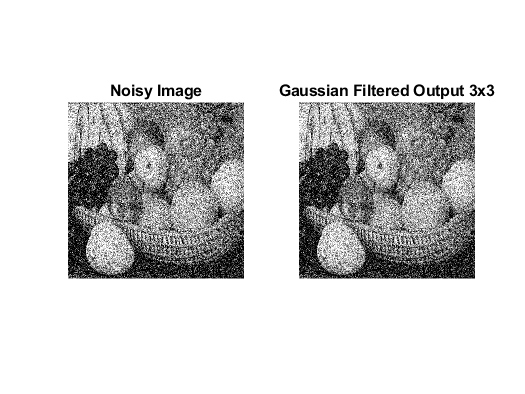

kernel = fspecial('gaussian',[3 3],0.33);         

IGG = imfilter(noisyGauss,kernel); % Gaussian filter on image with gaussian noise
figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(IGG),title('Gaussian Filtered Output 3x3')


%% Calculation of SNR
SNR_gf_3=10*log10((sum(double(noisyGauss).^2))/sum((double(IGG)-double(I)).^2))

SNR_gf_3 = 9.0164

**Gaussian filter of size 7 × 7**

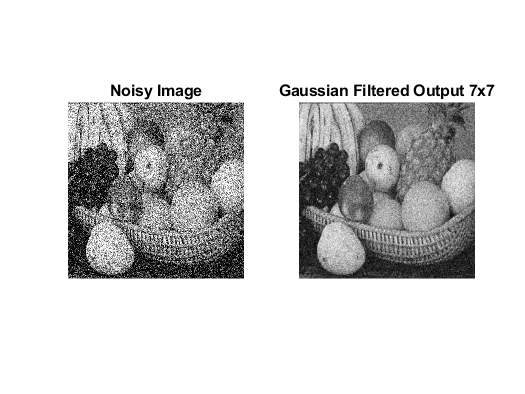

kernel = fspecial('gaussian',[7 7],1);         

IGG_7 = imfilter(noisyGauss,kernel); % Gaussian filter on image with gaussian noise

figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(IGG_7),title('Gaussian Filtered Output 7x7')


%% Calculation of SNR
SNR_gf_7=10*log10((sum(double(noisyGauss).^2))/sum((double(IGG_7)-double(I)).^2))

SNR_gf_7 = 17.8868

**Gaussian filter of size 11 × 11**

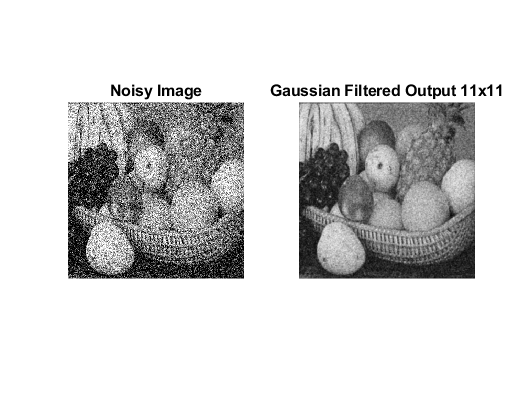

kernel = fspecial('gaussian',[11 11],1.333);         

IGG_11 = imfilter(noisyGauss,kernel);  % Gaussian filter on image with gaussian noise

figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(IGG_11),title('Gaussian Filtered Output 11x11')


%% Calculation of SNR
SNR_gf_11=10*log10((sum(double(noisyGauss).^2))/sum((double(IGG_11)-double(I)).^2))

SNR_gf_11 = 18.1658

### For gaussian, SNR is increasing with the size. 

### 2. Filter the noisy image with an average filterof size 3 × 3, 7 × 7 then 11 × 11. Compare with Gaussian filters of same sizes. 

**Average filter of size 3 × 3**

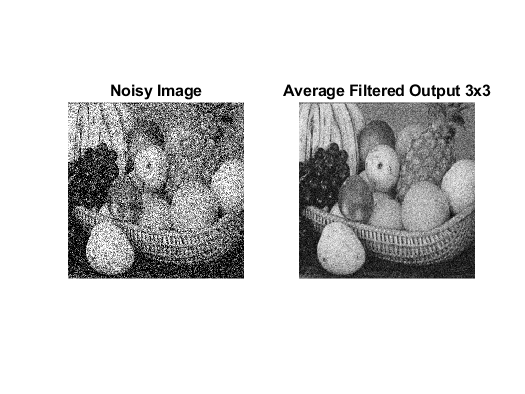

% % Generate average filter

kernel = fspecial('average', [3 3]);         

Avg_3 = imfilter(noisyGauss,kernel); % Average filter  on image with gaussian noise

figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(Avg_3),title('Average Filtered Output 3x3')


%% Calculation of SNR

SNR_Avg_3=10*log10((sum(double(noisyGauss).^2))/sum((double(Avg_3)-double(I)).^2))

SNR_Avg_3 = 16.9824

**Average filter of size 7 × 7**

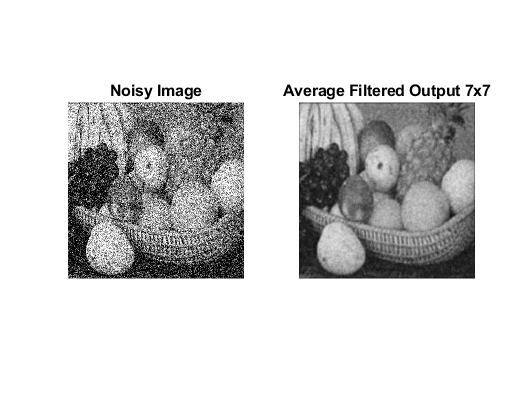

kernel = fspecial('average', [7 7]);         

Avg_7 = imfilter(noisyGauss,kernel); % Average filter  on image with gaussian noise

figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(Avg_7),title('Average Filtered Output 7x7')


%% Calculation of SNR

SNR_Avg_7=10*log10((sum(double(noisyGauss).^2))/sum((double(Avg_7)-double(I)).^2))

SNR_Avg_7 = 16.4894

**Average filter of size 11 × 11**

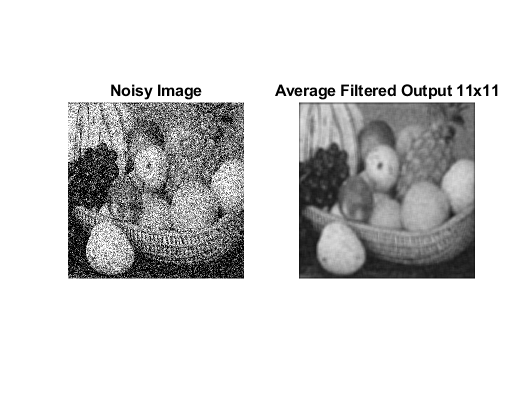

kernel = fspecial('average', [11 11]);         

Avg_11 = imfilter(noisyGauss,kernel); % Average filter  on image with gaussian noise
figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(Avg_11),title('Average Filtered Output 11x11')


%% Calculation of SNR

SNR_Avg_11=10*log10((sum(double(noisyGauss).^2))/sum((double(Avg_11)-double(I)).^2))

SNR_Avg_11 = 15.0410

Average filters do not significantly reduce Gaussian noise. We can still tell the noisy pixels apart. Because each output pixel value is the mean of all the values of its neighboring pixels, when a noisy pixel is included in the neighborhood, its extreme value (0 and 255) is used to compute the mean. The blurring increases as the average filter size increases.

### 3. Filter the noisy image with a median filter of size 3×3, 7×7 then 11×11. Compare with the previous filters.

### Median filter of size 3×3

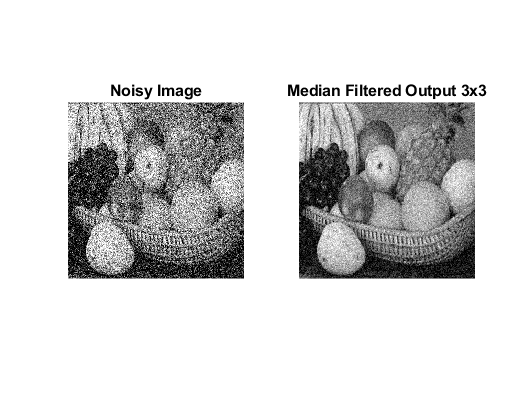

med_3 = medfilt2(noisyGauss,[3 3]);
figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(med_3),title('Median Filtered Output 3x3')


%% Calculation of SNR

SNR_Med_3=10*log10((sum(double(noisyGauss).^2))/sum((double(med_3)-double(I)).^2))

SNR_Med_3 = 15.5037

### Median filter of size 7×7

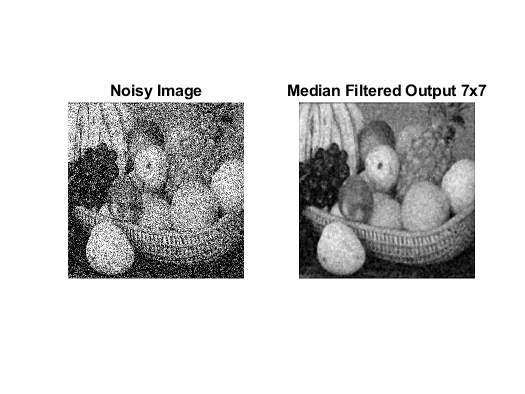

med_7 = medfilt2(noisyGauss,[7 7]);
figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(med_7),title('Median Filtered Output 7x7')


%% Calculation of SNR

SNR_Med_7=10*log10((sum(double(noisyGauss).^2))/sum((double(med_7)-double(I)).^2))

SNR_Med_7 = 16.6820

### Median filter of size 11×11

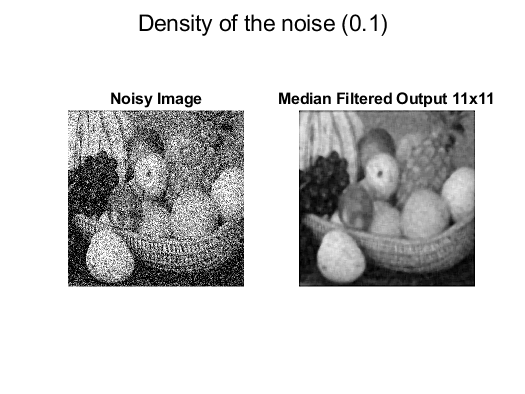

med_11 = medfilt2(noisyGauss,[11 11]);
figure,
subplot(121),imshow(noisyGauss),title('Noisy Image'),
subplot(122),imshow(med_11),title('Median Filtered Output 11x11')


%% Calculation of SNR

SNR_Med_11=10*log10((sum(double(noisyGauss).^2))/sum((double(med_11)-double(I)).^2))

SNR_Med_11 = 14.7862

Gaussian filter is a linear type of filter which is based on Gaussian function. But the median filter is a non-linear type of filter. It preserves edge while removing noise. One advantage a Gaussian filter has over a median filter is that it's faster because multiplying and adding is probably faster than sorting. The median filter has two main advantages over the mean filter:

- The median is a more robust average than the mean and so a single very unrepresentative pixel in a neighborhood will not affect the median value significantly.

- Since the median value must actually be the value of one of the pixels in the neighborhood, the median filter does not create new unrealistic pixel values when the filter straddles an edge. For this reason the median filter is much better at preserving sharp edges than the mean filter.

### **SNR table**

Type = ["3x3"; "7x7"; "1x11"];
Gaussian = [SNR_gf_3; SNR_gf_7; SNR_gf_11];
Average = [SNR_Avg_3; SNR_Avg_7; SNR_Avg_11];
Median = [SNR_Med_3; SNR_Med_7; SNR_Med_11];
SNRtable = table(Type,Gaussian,Average,Median)

SNRtable = 3×4 table
     Type     Gaussian    Average    Median
    ______    ________    _______    ______

    "3x3"      9.0164     16.982     15.504
    "7x7"      17.887     16.489     16.682
    "1x11"     18.166     15.041     14.786


The SNR is a parameter independent of the type of noise, but its results and usability are very related to how the image is degraded. SNR is useful with uniformly random noise (like gaussian) but give bad results ond localized and non linear degradation (like threshold degradation or loss of a specific area). 

### Exercise 3 : Spatial High pass filters 

### 1. Calculate the modulus is the orientation of the gradient using a Sobel filter on the image of your choice. Comment. 

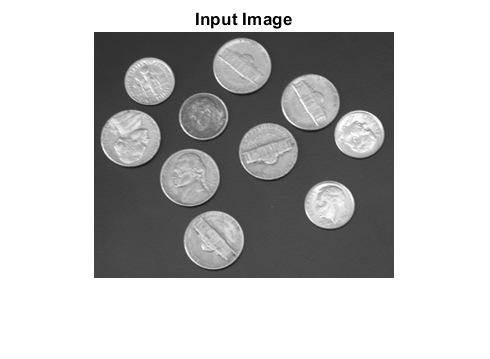

% Read Input Image
input_image = imread('coins.png');

% Displaying Input Image
input_image = uint8(input_image);
figure, imshow(input_image); title('Input Image');

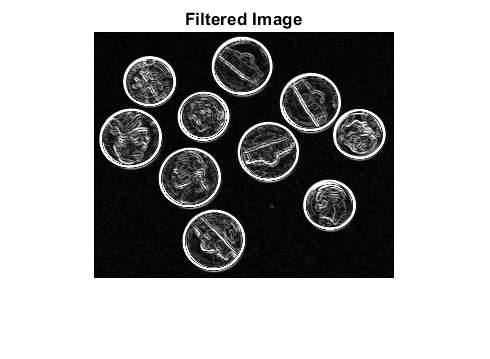


% Convert the image to double
input_image = double(input_image);

% Pre-allocate the filtered_image matrix with zeros
filtered_image = zeros(size(input_image));

% Sobel Operator Mask
Mx = [-1 0 1; -2 0 2; -1 0 1];
My = [-1 -2 -1; 0 0 0; 1 2 1];

% Edge Detection Process
% When i = 1 and j = 1, then filtered_image pixel
% position will be filtered_image(2, 2)
% The mask is of 3x3, so we need to traverse
% to filtered_image(size(input_image, 1) - 2
%, size(input_image, 2) - 2)
for i = 1:size(input_image, 1) - 2
	for j = 1:size(input_image, 2) - 2

		% Gradient approximations
		Gx = sum(sum(Mx.*input_image(i:i+2, j:j+2)));
		Gy = sum(sum(My.*input_image(i:i+2, j:j+2)));
				
		% Calculate magnitude of vector
		filtered_image(i+1, j+1) = sqrt(Gx.^2 + Gy.^2);
		
	end
end

% Displaying Filtered Image
filtered_image = uint8(filtered_image);
figure, imshow(filtered_image); title('Filtered Image');

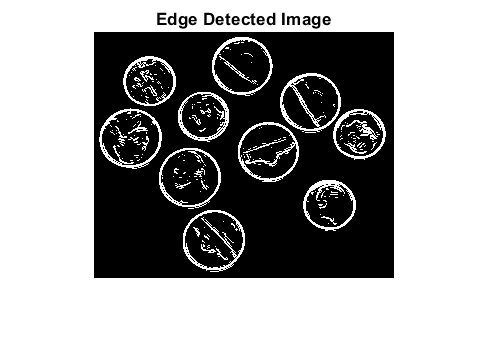


% Define a threshold value
thresholdValue = 100; % varies between [0 255]
output_image = max(filtered_image, thresholdValue);
output_image(output_image == round(thresholdValue)) = 0;

% Displaying Output Image
output_image = im2bw(output_image);
figure, imshow(output_image); title('Edge Detected Image');

Sobel Operator is a discrete differentiation gradient-based operator. It computes the gradient approximation of image intensity function for image edge detection. At the pixels of an image, the Sobel operator produces either the normal to a vector or the corresponding gradient vector. It uses two 3 x 3 kernels or masks which are convolved with the input image to calculate the vertical and horizontal derivative. It has certain edges which are

a. Simple and time efficient computation.

b. Very easy at searching for smooth edges.

### 2. Convolve the image with a Laplacian 3 × 3. Determine zero crossings.

The zero crossing detector looks for places in the Laplacian of an image where the value of the Laplacian passes through zero --- *i.e.* points where the Laplacian changes sign.  

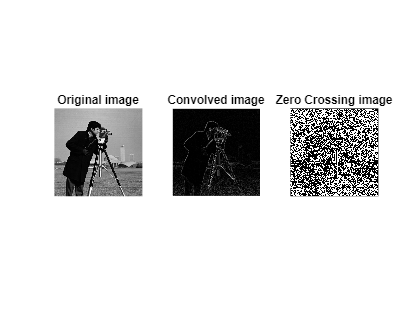

k1 = imread('cameraman.tif');
% Define the Laplacian filter.
Laplacian=[0 1 0; 1 -4 1; 0 1 0];
 
% Convolve the image using Laplacian Filter
k2=conv2(k1, Laplacian, 'same');

k3 =  zeros(size(k2));

for i = 1:(size(k1,1)-1)
    for j = 1:(size(k1,2)-1)
        if(k2(i,j+1) > 0 && k2(i,j)< 0)
            k3(i,j) = 1; 
        elseif(k2(i,j+1) < 0 && k2(i,j)> 0)
            k3(i,j) = 1;

        end
    end
end

% Display the image.
figure,
subplot(1,3,1), imshow(k1, []), title('Original image');
subplot(1,3,2), imshow(abs(k2),[]), title('Convolved image');
subplot(1,3,3), imshow(abs(k3),[]), title('Zero Crossing image');

### 3. Convolve the image with a LOG then a DOG of size 5 × 5 suitably generated. Plot the profiles of the two filters. Determine zero crossing.

The Laplacian of Gaussian method finds edges by looking for zero crossings after filtering `I` with a Laplacian of Gaussian filter. First Derivative Filters changes sharp in gray level of the input image correspond to “peaks or valleys” of the first-derivative of the input signal. Again peaks of the first-derivative of the input signal, correspond to “zero-crossings” of the second-derivative of the input signal. An alternative approch to finding edges as peaks in first deriv is to find zero-crossings in second deriv.

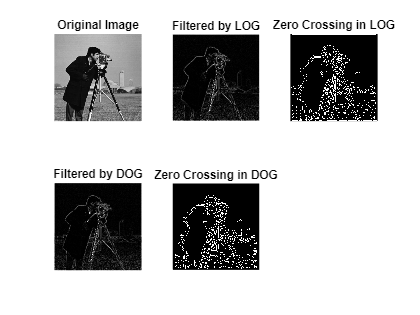

f1=fspecial('log');
Ilog = conv2(k1, f1, 'same');

zeros_corssings_log=edge(Ilog, 'zerocross');

%DOG
H1 = fspecial('gaussian',[5 5], 0.3);
H2 = fspecial('gaussian', [5 5],0.8);
dog = H1 - H2;
Dog_filter = conv2(k1,dog,'same');

zeros_corssings_dog=edge(Dog_filter, 'zerocross');


figure
subplot (231)
imshow(k1)
title ('Original Image')
subplot (232)
imshow (abs(Ilog), [])
title('Filtered by LOG')
subplot (233)
imshow (abs(zeros_corssings_log), [])
title('Zero Crossing in LOG')

subplot (234)
imshow (abs(Dog_filter), [])
title('Filtered by DOG')

subplot (235)
imshow (abs(zeros_corssings_dog), [])
title('Zero Crossing in DOG')

In LOG, first smooth (Gaussian filter) has been applied. Then, zero-crossings (Laplacian filter) needs to be found. 

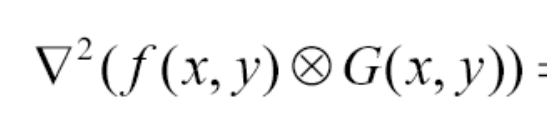

LoG can be approximate by a Difference of two Gaussians (DoG) at different scales. Separability of and cascadability of Gaussians applies to the DoG, so we can achieve efficient implementation of the LoG operator. DoG approx also explains bandpass filtering of LoG.

## Exercise 4 : Simple enhancement using histograms 

### 1. Load these images: cameraman, kids, pout and flowers (imread then imshow). Change the colormaps using matlab colormaps Matlab (PINK, HSV, GRAY, HOT, COOL, BONE, COPPER , FLAG). 

img1 = imread('cameraman.tif');
img2 = imread('kids.tif');
img3 = imread('pout.tif');
img4 = imread('FRUIT_LUMI.BMP');

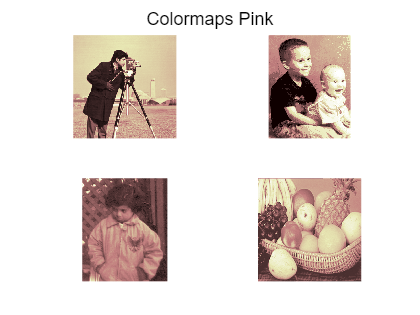

figure,
subplot(2,2,1), imshow(img1, []), colormap("pink")
subplot(2,2,2),imshow(img2, []), colormap("pink")
subplot(2,2,3),imshow(img3, []), colormap("pink") 
subplot(2,2,4),imshow(img4, []), colormap("pink"),
sgtitle('Colormaps Pink') 

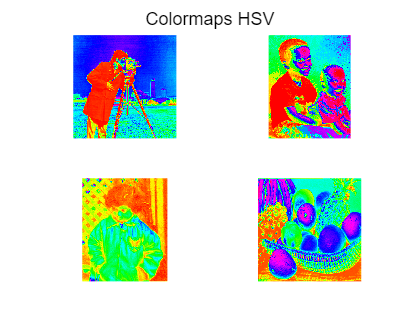


figure,
subplot(2,2,1),imshow(img1, []), colormap("hsv")
subplot(2,2,2),imshow(img2, []), colormap("hsv")
subplot(2,2,3),imshow(img3, []), colormap("hsv") 
subplot(2,2,4),imshow(img4, []), colormap("hsv") 
sgtitle('Colormaps HSV') 

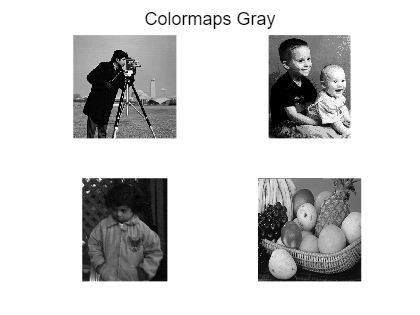


figure,
subplot(2,2,1),imshow(img1, []), colormap("gray")
subplot(2,2,2),imshow(img2, []), colormap("gray")
subplot(2,2,3),imshow(img3, []), colormap("gray") 
subplot(2,2,4),imshow(img4, []), colormap("gray") 
sgtitle('Colormaps Gray') 

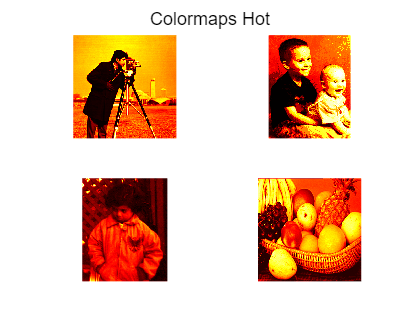


figure,
subplot(2,2,1),imshow(img1, []), colormap("hot")
subplot(2,2,2),imshow(img2, []), colormap("hot")
subplot(2,2,3),imshow(img3, []), colormap("hot") 
subplot(2,2,4),imshow(img4, []), colormap("hot") 
sgtitle('Colormaps Hot') 

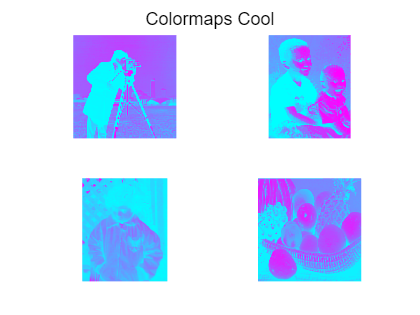


figure,
subplot(2,2,1),imshow(img1, []), colormap("cool")
subplot(2,2,2),imshow(img2, []), colormap("cool")
subplot(2,2,3),imshow(img3, []), colormap("cool") 
subplot(2,2,4),imshow(img4, []), colormap("cool") 
sgtitle('Colormaps Cool') 

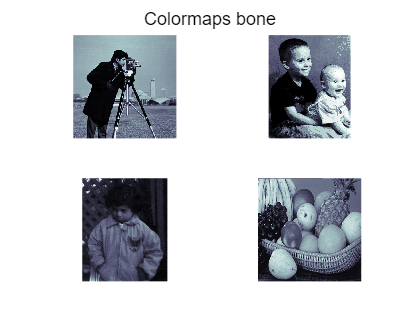


figure,
subplot(2,2,1),imshow(img1, []), colormap("bone")
subplot(2,2,2),imshow(img2, []), colormap("bone")
subplot(2,2,3),imshow(img3, []), colormap("bone")
subplot(2,2,4),imshow(img4, []), colormap("bone") 
sgtitle('Colormaps bone') 

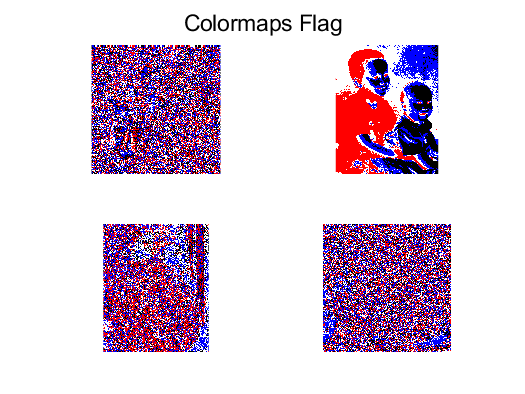


figure,
subplot(2,2,1),imshow(img1, []), colormap("flag")
subplot(2,2,2),imshow(img2, []), colormap("flag")
subplot(2,2,3),imshow(img3, []), colormap("flag")
subplot(2,2,4),imshow(img4, []), colormap("flag")
sgtitle('Colormaps Flag') 

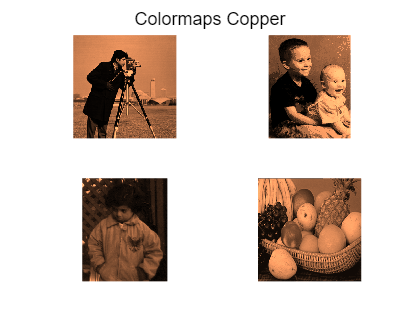



figure,
subplot(2,2,1),imshow(img1, []), colormap("copper")
subplot(2,2,2),imshow(img2, []), colormap("copper")
subplot(2,2,3),imshow(img3, []), colormap("copper")
subplot(2,2,4),imshow(img4, []), colormap("copper")
sgtitle('Colormaps Copper') 

### 2. Display pixel values and corresponding values in the colormap in a small neighborhood (imtool). Focus on homogeneous regions. Conclude. 

% x1 = imtool(img1,'Colormap',gray);

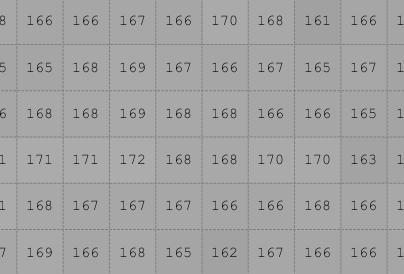

As these pixels are neighbour, it is expected to have similar pixel intensity. But in the reality, the pixel's intensity is differnet even though they are in the same homogenous area.

% x2 = imtool(img1,'Colormap',hsv);
% x3 = imtool(img1,'Colormap',pink);
% x4 = imtool(img1,'Colormap',hot);
% x5 = imtool(img1,'Colormap',cool);
% x6 = imtool(img1,'Colormap',bone);
% x7 = imtool(img1,'Colormap',copper);
% x8 = imtool(img1,'Colormap',flag);


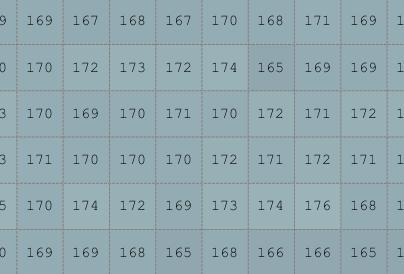

Figure: Pixel associated in the same area in colormap bone.

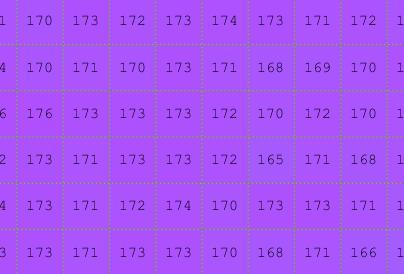

Figure: Pixel associated in the same area in colormap cool.

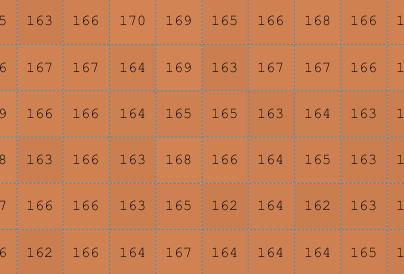

Figure: Pixel associated in the same area in colormap copper.

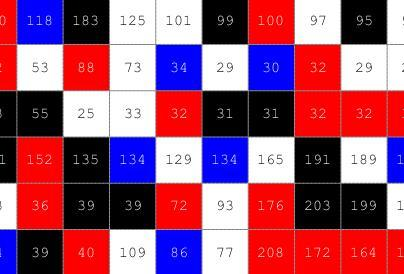

Figure: Pixel associated in the same area in colormap flag.

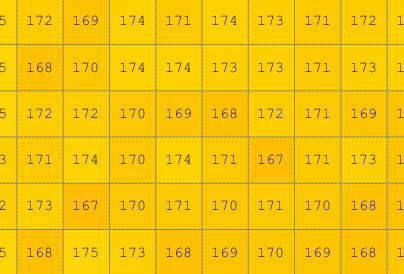

Figure: Pixel associated in the same area in colormap hot.

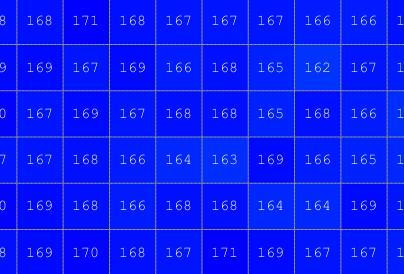

Figure: Pixel associated in the same area in colormap bone.

### 3. Compare the characteristics of these images using imfinfo: format, resolution, dynamics. Note for each image the mean, the variance as well as the min and max values. Make a link between these values and the visual quality of the images. 

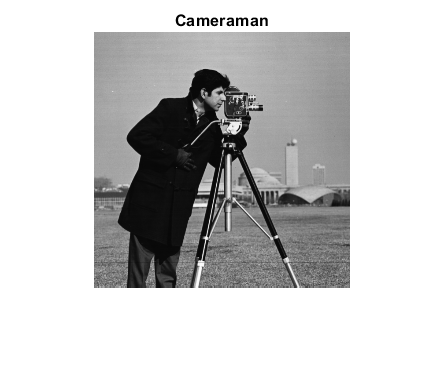

figure
imshow(img1)
title('Cameraman')

info_cameraman= imfinfo('cameraman.tif')

info_cameraman = struct with fields:
                     Filename: 'C:\Program Files\MATLAB\R2021b\toolbox\images\imdata\cameraman.tif'
                  FileModDate: '04-Dec-2000 19:57:54'
                     FileSize: 65240
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [77 77 0 42]
                    ByteOrder: 'big-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 8262 16426 24578 32492 40499 48599 56637]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [8254 8164 8152 7914 8007 8100 8038 8235]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit:

max_img1 = max(img1(:))

max_img1 = uint8
253

min_img1 = min(img1(:))

min_img1 = uint8
7

mean_img1 = mean(img1(:))

mean_img1 = 118.7245

var_img1 = var(double(img1(:)))

var_img1 = 3.8865e+03

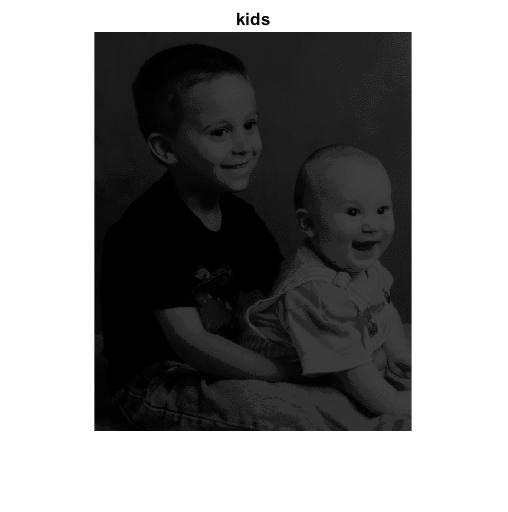


figure
imshow(img2)
title('kids')

info_kids= imfinfo('kids.tif')

info_kids = struct with fields:
                     Filename: 'C:\Program Files\MATLAB\R2021b\toolbox\images\imdata\kids.tif'
                  FileModDate: '13-Apr-2015 15:23:13'
                     FileSize: 97058
                       Format: 'tif'
                FormatVersion: []
                        Width: 318
                       Height: 400
                     BitDepth: 8
                    ColorType: 'indexed'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB Palette'
                 StripOffsets: [8 6746 13099 19718 26206 32745 39380 45437 51321 55273 59481 64675 70359 75726 81203 87177]
              SamplesPerPixel: 1
                 RowsPerStrip: 25
              StripByteCounts: [6738 6353 6619 6488 6539 6635 6057 5884 3952 4208 5194 5684 5367 5477 5974 6130]
                  X

max_img2 = max(img2(:))

max_img2 = uint8
63

min_img2 = min(img2(:))

min_img2 = uint8
0

mean_img2 = mean(img2(:))

mean_img2 = 26.1343

var_img2 = var(double(img2(:)))

var_img2 = 369.7469

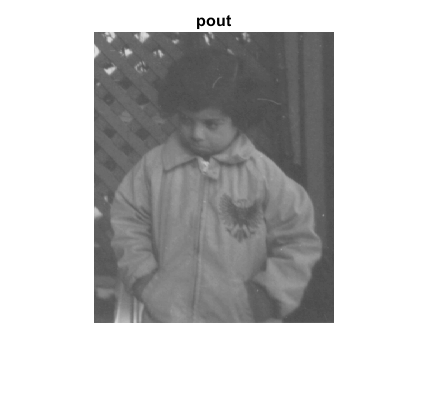



figure
imshow(img3)
title('pout')

info_pout= imfinfo('pout.tif')

info_pout = struct with fields:
                     Filename: 'C:\Program Files\MATLAB\R2021b\toolbox\images\imdata\pout.tif'
                  FileModDate: '13-Apr-2015 15:23:13'
                     FileSize: 69296
                       Format: 'tif'
                FormatVersion: []
                        Width: 240
                       Height: 291
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 7984 15936 23976 32089 40234 48335 56370 64301]
              SamplesPerPixel: 1
                 RowsPerStrip: 34
              StripByteCounts: [7976 7952 8040 8113 8145 8101 8035 7931 4452]
                  XResolution: 72
                  YResolution: 72
               ResolutionU

max_img3 = max(img3(:))

max_img3 = uint8
224

min_img3 = min(img3(:))

min_img3 = uint8
74

mean_img3 = mean(img3(:))

mean_img3 = 110.3037

var_img3 = var(double(img3(:)))

var_img3 = 537.3647

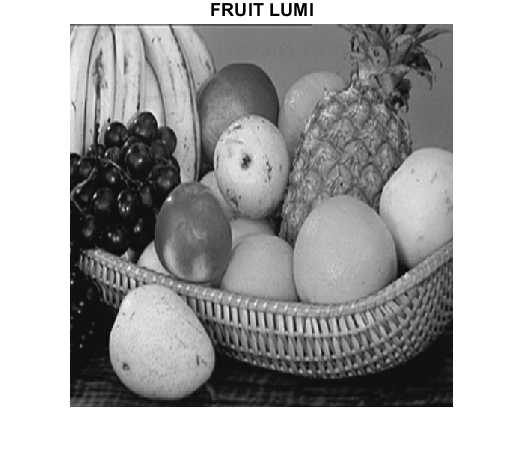


figure
imshow(img4)
title('FRUIT LUMI')

info_fruit= imfinfo('FRUIT_LUMI.BMP')

info_fruit = struct with fields:
              Filename: 'D:\Masters\M1\Semester 2\Image and signal processing\TP\Tp2\linearFilter-20220406T113755Z-001\linearFilter\FRUIT_LUMI.BMP'
           FileModDate: '05-Apr-2022 08:01:56'
              FileSize: 263222
                Format: 'bmp'
         FormatVersion: 'Version 3 (Microsoft Windows 3.x)'
                 Width: 512
                Height: 512
              BitDepth: 8
             ColorType: 'indexed'
       FormatSignature: 'BM'
    NumColormapEntries: 256
              Colormap: [256×3 double]
               RedMask: []
             GreenMask: []
              BlueMask: []
       ImageDataOffset: 1078
      BitmapHeaderSize: 40
             NumPlanes: 1
       CompressionType: 'none'
            BitmapSize: 0
        HorzResolution: 0
        VertResolution: 0
         NumColorsUsed: 256
    NumImportantColors: 0


max_img4 = max(img4(:))

max_img4 = uint8
255

min_img4 = min(img4(:))

min_img4 = uint8
3

mean_img4 = mean(img4(:))

mean_img4 = 116.7825

var_img4 = var(double(img4(:)))

var_img4 = 3.7030e+03

Standard deviation measure the deviation of measured Values or the data from its mean. When Standard deviation is near zero, the measured values are near the mean and all converging. But when Standard deviation is high, the Values or the data are scattered and at the same time far from the mean. Contrast is high for images with high standard deviation values. Maximum and minimum intensity value relates to the grayscale image where the higher the intensity value, the lighten it will be. In opposite, the lower pixel value signifies the darkness of the pixels. 

### 4. Calculate and display the histogram of each of the images. Make a link between the histogram and the content of the images when possible.

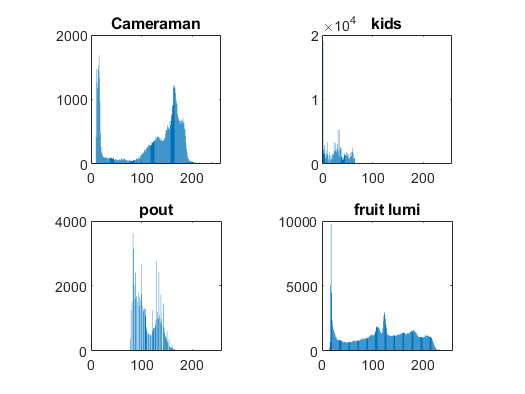

imhisto1 = hist(img1(:),[0:255]);
imhisto2 = hist(img2(:),[0:255]);
imhisto3 = hist(img3(:),[0:255]);
imhisto4 = hist(img4(:),[0:255]);

figure
subplot(2,2,1), bar(imhisto1),title('Cameraman'), axis square,
subplot(2,2,2), bar(imhisto2),title('kids'), axis square,
subplot(2,2,3), bar(imhisto3),title('pout'), axis square,
subplot(2,2,4), bar(imhisto4),title('fruit lumi'), axis square,

In Cameraman, there are two peaks. The first peak represents the camerma’s intensity values (specially his outfit). Similarly, the image intensity values near the second represent the intensity values of the background region .

In Kids, there are one broken peaks. The peak represents the Kids' face intensity values (specially his outfit). 

In Pout, there are two peaks. One bigger and one smaller. The first peak represents the background’s intensity values. Similarly, the image intensity values near the smaller peak represent the intensity values of the child's shape.

In Fruit lumi, there is one really big peaks. The peak represents the grape’s intensity values. The rest of the intensity values represent the intensity values of the other fruits .

### 5. In order to improve contrast, apply a point function to the image: linear, exponential then logarithmic. Explain the role of each function and configure them appropriately. Apply them to the images that are best suited to each function. Compare the histograms before and after application of each function. 

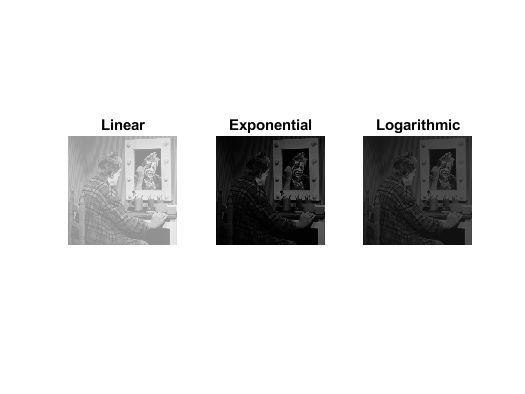

img1 =imread('CLOWN_LUMI.BMP'); 
img2=im2double(img1);
[m,n]=size(img2);
linimg = zeros(m,n);
logimg = zeros(m,n);
expimg = zeros(m,n);
factor = 0.5;
for i= 1:m
    for j= 1:n
        linimg(i,j)=factor*img2(i,j)+ 0.5;
        logimg(i,j)=factor*log(1+img2(i,j));
        expimg(i,j)=factor*img2(i,j)^2;  
    end
end

figure
subplot(131), imshow(linimg), title('Linear')
subplot(132), imshow(expimg), title('Exponential')
subplot(133), imshow(logimg), title('Logarithmic')

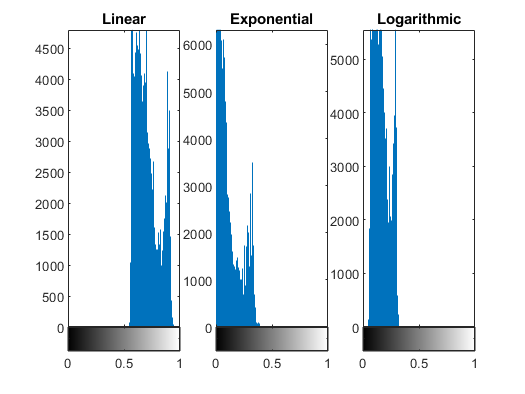


figure
subplot(131), imhist(linimg), title('Linear')
subplot(132), imhist(expimg), title('Exponential')
subplot(133), imhist(logimg), title('Logarithmic')

Linear: Linear Transformation is type of gray level transformation that is used for image enhancement. It is a spatial domain method. It is used for manipulation of an image so that the result is more suitable than the original for a specific application.

Exponential: An exponential function is a point process with an exponential mapping function. This implies that each pixel intensity value in the output image is equivalent to a basis value multiplied by the relating pixel intensity value in the input image.

Logarithmic: Logarithmic transformation of an image is one of the gray level image transformations. Log transformation of an image means replacing all pixel values, present in the image, with its logarithmic values. Log transformation is used for image enhancement as it expands dark pixels of the image as compared to higher pixel values.

6. Compare previous fonctions with histogram equalization (histeq).

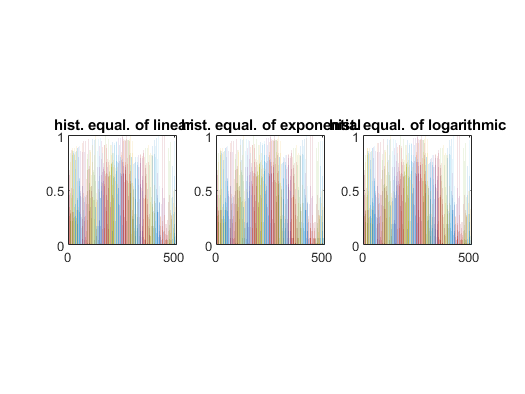

linimg_eq = histeq(linimg);
expimg_eq = histeq(expimg);
logimg_eq = histeq(logimg);
figure,
subplot(1,3,1); bar(linimg_eq), axis square, title('hist. equal. of linear'); 
subplot(1,3,2), bar(expimg_eq), axis square, title('hist. equal. of exponential'); 
subplot(1,3,3), bar(logimg_eq), axis square, title('hist. equal. of logarithmic');

 7. Use the histogram to find the best threshold for the coins, blood1 and rice images. Do the same with an image of your choice. 

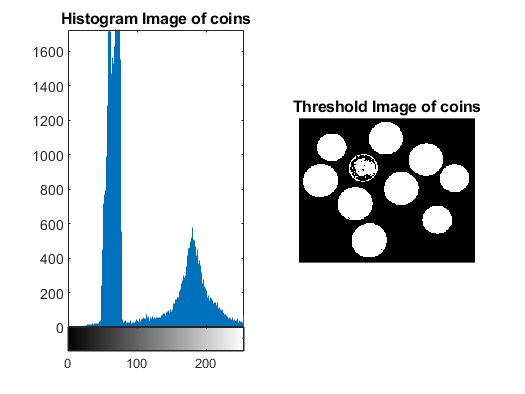

img1 = imread('coins.png');
figure,
subplot(1,2,1),imhist(img1), title('Histogram Image of coins');
threshold = 120;
bw1        = img1>threshold;
subplot(1,2,2), imshow(bw1, []),title('Threshold Image of coins')

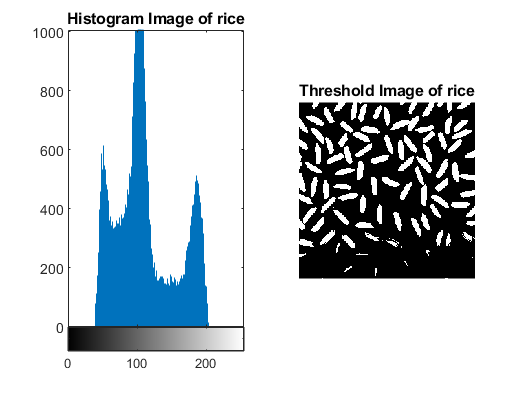


img2 = imread('rice.png');
figure,
subplot(1,2,1), imhist(img2), title('Histogram Image of rice');
threshold1 = 143;
bw2 = img2>threshold1;
subplot(1,2,2), imshow(bw2, []),title('Threshold Image of rice')

8. Compare the adaptive thresholding method (to be implemented) with Otsu’s method (graythresh) on the previous images and on the image of your choice. Carefully keep the binary images obtained for the following exercise. 

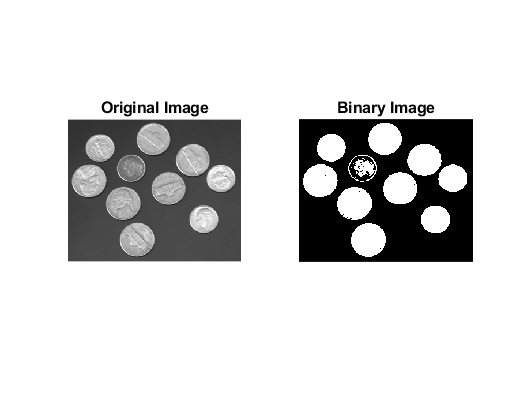

I1 = imread('coins.png');
figure,
subplot(1,2,1); imshow(I1), title('Original Image');
thresh_coin = graythresh(I1); % Find threshold value using Otsu method
subplot(1,2,2); im2bw(I1,thresh_coin),title('Binary Image') ;

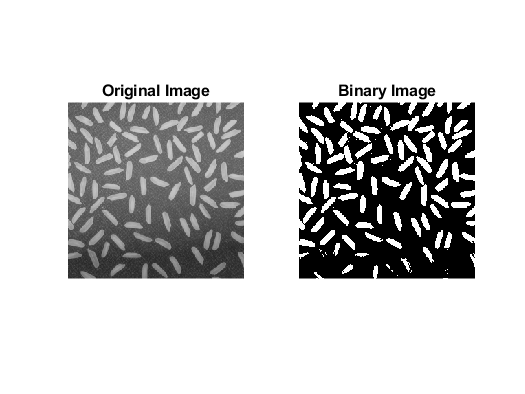


I2 = imread('rice.png');
figure,
subplot(1,2,1); imshow(I2), title('Original Image');
thresh_rice = graythresh(I2); % Find threshold value using Otsu method
subplot(1,2,2); im2bw(I2,thresh_rice), title('Binary Image');

## Segmentation 

## Exercise 5 : Highlighting zones 

### 1. On the previous thresholded images (you will choose the best result obtained), apply a labeling in connected components (blob coloring) (bwlabel then label2rgb).

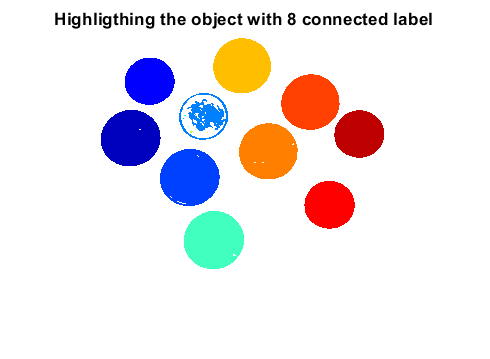

L8 = bwlabel(im2bw(I1,thresh_coin));
RGB = label2rgb(L8);
figure,
imshow(RGB), title('Highligthing the object with 8 connected label')

###  2. Compare 4-connected labeling with 8-connected labeling. 

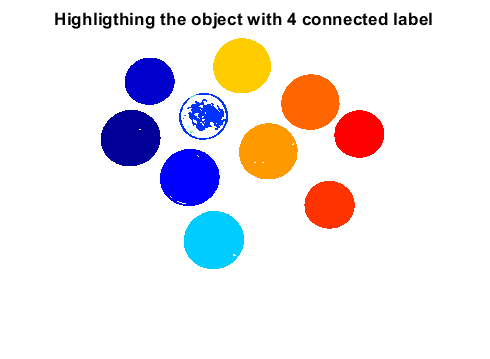

L4 = bwlabel(im2bw(I1,thresh_coin), 4);
RGB_4 = label2rgb(L4);
figure
imshow(RGB_4), title('Highligthing the object with 4 connected label')

4-connected region: from a given pixel one can get to any other pixel in the region by a series of 4 way moves (up, down,left, right).

8-connected region: from a given pixel one can get to any other pixel in the region by a series of 8 way moves (up, down,left, right, up-left, up-right, down-left, down-right).

 Note:1) An 8-connected boundary defines a 4-connected region2) If something is 4-connected, it is also 8-connected.

 4 connected for labelling, one will probably get more objects.

### 3. Find a simple way to calculate the area in pixels of labeled objects. 

Area = regionprops(L8, 'Area')

Area = 15×1 struct array with fields:
    Area


### 4. Perform edge detection (as in Exercise 3) starting from the labeled image. What do you deduce from this?

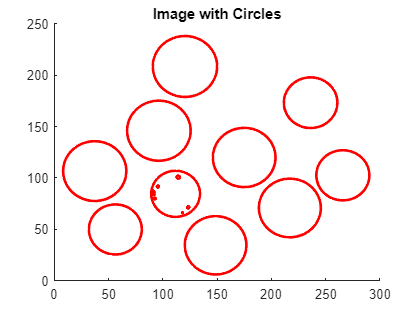

bw = img1>threshold;
figure,
title('Image with Circles')

stats = regionprops('table',bw,'Centroid',...
    'MajorAxisLength','MinorAxisLength');

centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
hold on
viscircles(centers,radii);
hold off

From the final image, it can be deduced that the edges of the circles are explicitly visible. 